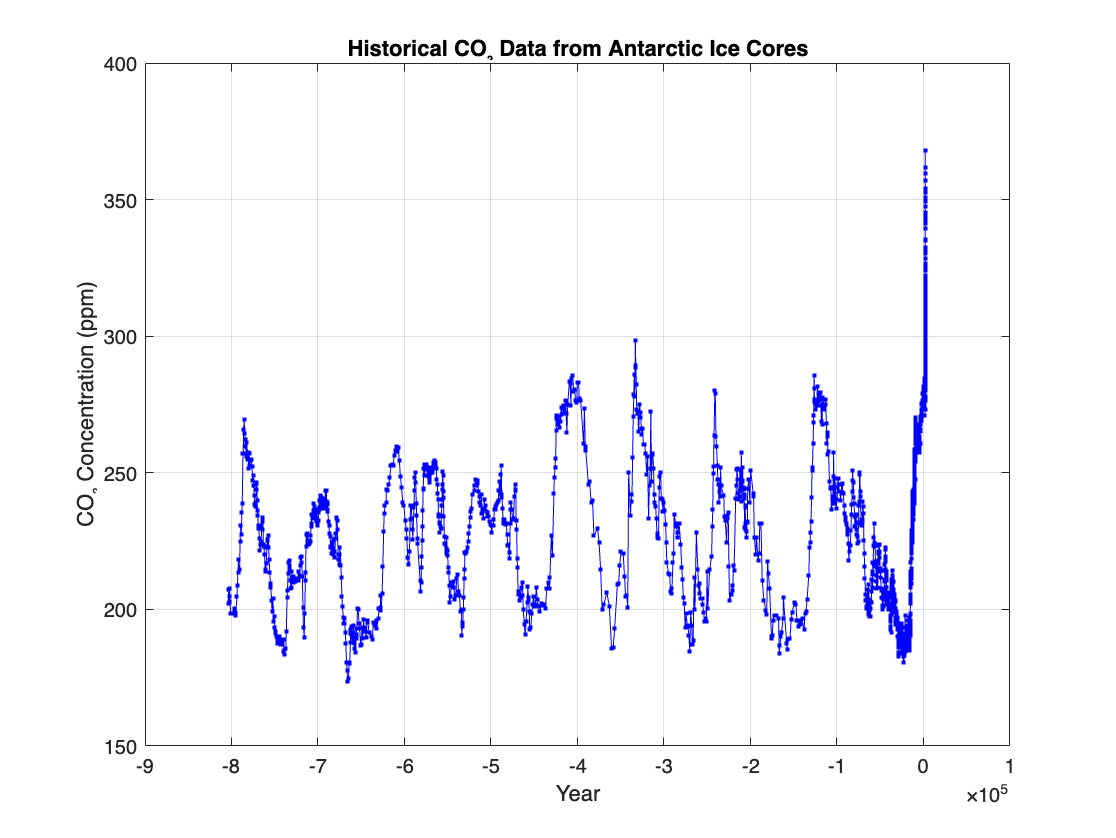

% Main section of the LiveScript

% Call the subfunction with the filename
[iceCO2Years, iceCO2] = readIceCoreCO2Data('antarctica2015co2composite.txt');

% Plot the data to verify correctness
figure;
plot(iceCO2Years, iceCO2, 'b.-');
xlabel('Year');
ylabel('CO₂ Concentration (ppm)');
title('Historical CO₂ Data from Antarctic Ice Cores');
grid on;


% Subfunction definition
function [years, co2] = readIceCoreCO2Data(filename)
    % Open the file for reading
    fid = fopen(filename, 'r');
    if fid == -1
        error('Cannot open file: %s', filename);
    end

    % Initialize cell arrays to store data
    yearsBP = {};
    co2 = {};

    % Read the file line by line
    while ~feof(fid)
        line = fgetl(fid);
        if ischar(line)
            % Attempt to convert the line to numeric values
            numericData = str2num(line); %#ok<ST2NM>
            if ~isempty(numericData) && numel(numericData) >= 2
                % Store the first two numeric values
                yearsBP{end+1} = numericData(1); %#ok<AGROW>
                co2{end+1} = numericData(2); %#ok<AGROW>
            end
        end
    end

    % Close the file
    fclose(fid);

    % Convert cell arrays to numeric vectors
    yearsBP = cell2mat(yearsBP);
    co2 = cell2mat(co2);

    % Convert years before 1950 to Gregorian calendar years
    years = 1950 - yearsBP;

    % Flip the vectors to have the oldest data first
    years = flipud(years);
    co2 = flipud(co2);
end
